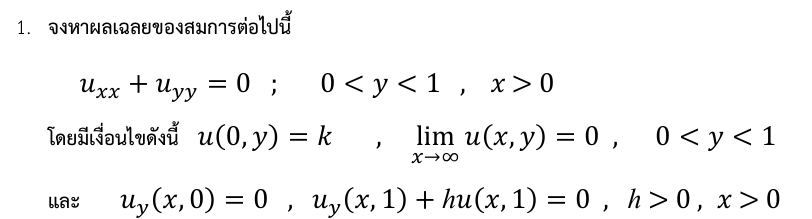

clear;clc;clearvars;
syms x y k h lambda
assume(h > 0)
X = exp(-sqrt(lambda)*x); %x -> infinity
Y = symfun(cos(sqrt(lambda)*y), y) + symfun(sin(sqrt(lambda)*y), y); 
u_0y = k;
% condition)
dy_Y_at_0 = diff(Y, y, 1);
BC1 = subs(dy_Y_at_0, y, 0) == 0;
dy_Y_at_1 = diff(Y, y, 1);
BC2 = subs(dy_Y_at_1, y, 1) + h*subs(Y, y, 1) == 0;
sol_lambda = solve([BC1, BC2], lambda);
final_solution = X * Y

$$final\_solution(y) = {\mathrm{e}}^{-\sqrt{\lambda }\,x}\,\left(\cos\left(\sqrt{\lambda }\,y\right)+\sin\left(\sqrt{\lambda }\,y\right)\right)$$

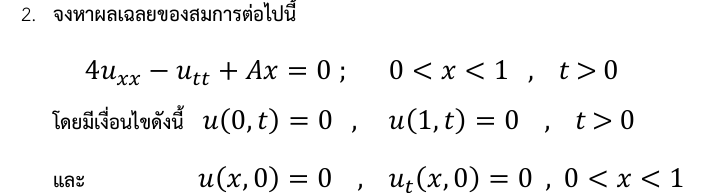

clearvars; clc;clf;
syms X(x) T(t) A u(x, t)
PDE = 4*diff(u, x, 2) - diff(u, t, 2) + A*x == 0;
u(x, t) = X(x) * T(t);
SepVar = subs(PDE, u(x, t), X(x)*T(t));
SepVar = simplify(SepVar / (X(x)*T(t))); % หารด้วย X(x)*T(t)
PDE_x = simplify(4*diff(X, x, 2) / X); % ส่วนของ x
PDE_t = simplify(-diff(T, t, 2) / T); % ส่วนของ t

% สมการต้องแยกเท่ากับค่าคงที่ -λ^2
syms lambda
ODE_x = PDE_x == lambda^2 % ODE ของ X(x)

$$ODE\_x(x) = \frac{4\,\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=\lambda^{2}$$

ODE_t = PDE_t == lambda^2 % ODE ของ T(t)

$$ODE\_t(t) = -\frac{\frac{\partial^{2}}{\partial t^{2}}T\left(t\right)}{T\left(t\right)}=\lambda^{2}$$


sol_X = dsolve(ODE_x) % แก้สมการ ODE สำหรับ X(x)

$$sol\_X = C_{1}\,{\mathrm{e}}^{-\frac{\lambda \,x}{2}}+C_{2}\,{\mathrm{e}}^{\frac{\lambda \,x}{2}}$$

sol_T = dsolve(ODE_t) % แก้สมการ ODE สำหรับ T(t)

$$sol\_T = C_{1}\,{\mathrm{e}}^{-\lambda \,t\,\mathrm{i}}+C_{2}\,{\mathrm{e}}^{\lambda \,t\,\mathrm{i}}$$

% นำผลลัพธ์ X(x) และ T(t) มารวมเป็น u(x, t)
u_sol = sol_X * sol_T;

% แสดงผลลัพธ์
disp('ผลเฉลยของ u(x, t):');

ผลเฉลยของ u(x, t):


disp(u_sol);

$$\left(C_{1}\,{\mathrm{e}}^{-\lambda \,t\,\mathrm{i}}+C_{2}\,{\mathrm{e}}^{\lambda \,t\,\mathrm{i}}\right)\,\left(C_{1}\,{\mathrm{e}}^{-\frac{\lambda \,x}{2}}+C_{2}\,{\mathrm{e}}^{\frac{\lambda \,x}{2}}\right)$$

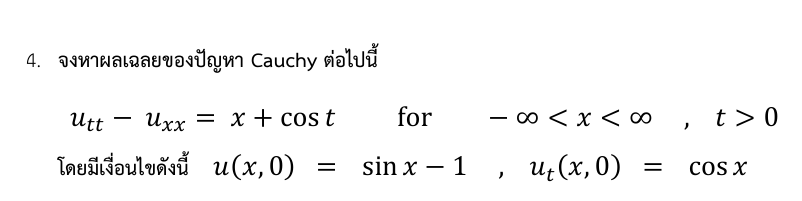

clear; clearvars; clf; clc;
% Parameters
L = 10;            % Spatial domain limit (-L to L)
N = 50;            % Number of spatial points
dx = 2 * L / (N-1); % Spatial step size
x = linspace(-L, L, N); % Spatial grid
T = 5;             % Time domain limit
dt = 0.01;         % Time step size
t = 0:dt:T;        % Time grid

% Wave equation parameters
c = 1; % Wave speed

% Initial conditions
u0 = sin(x) - 1;       % u(x, 0)
ut0 = cos(x);          % ut(x, 0)

% Initialize u for 3 time levels
u = zeros(N, length(t)); % Create the solution matrix
u(:,1) = u0;            % Initial condition u(x,0)

% Compute the second time level u(:,2) using Taylor expansion
for i = 2:N-1
    u(i,2) = u(i,1) + dt * ut0(i) + 0.5 * (dt^2) * ...
             ((u(i+1,1) - 2*u(i,1) + u(i-1,1)) / dx^2 + x(i) + cos(0)); % Using PDE
end

% Boundary conditions at the second time level
u(1,2) = 0; % Boundary at x = -L
u(N,2) = 0; % Boundary at x = L

% Finite difference loop
for n = 2:length(t)-1
    for i = 2:N-1
        % Wave equation: utt - uxx = x + cos(t)
        u(i,n+1) = 2*u(i,n) - u(i,n-1) + (c*dt/dx)^2 * (u(i+1,n) - 2*u(i,n) + u(i-1,n)) ...
                   + dt^2 * (x(i) + cos(t(n)));
    end
    % Boundary conditions (u = 0 at boundaries)
    u(1,n+1) = 0; % Boundary at x = -L
    u(N,n+1) = 0; % Boundary at x = L
end

% Visualization
[X, T] = meshgrid(x, t);
figure;
surf(X, T, u', 'EdgeColor', 'none');
xlabel('x');
ylabel('t');
zlabel('u(x,t)');
title('Solution of the Wave Equation');
colorbar;

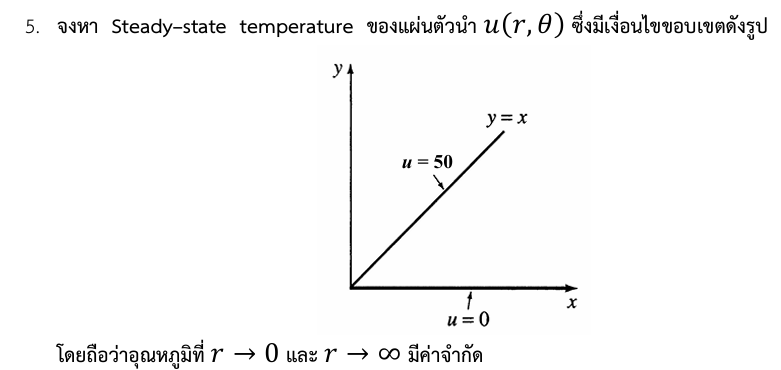

clc;
clear;
clearvars;
close all;
% Define parameters
N = 50; % Number of terms in the series
r = linspace(0, 2, 100); % Radial coordinate (0 to 2)
theta = linspace(0, pi/4, 100); % Angular coordinate (0 to pi/4)

% Create meshgrid for r and theta
[R, Theta] = meshgrid(r, theta);

% Initialize solution u
U = zeros(size(R));

% Solve using separation of variables
for n = 1:N
    % Coefficient (A_n)
    An = (2 / (n * pi)) * (1 - cos(n * pi / 4));
    % Add term to the solution
    U = U + An * sin(n * Theta) .* (R .^ n);
end

% Convert to Cartesian coordinates for visualization
X = R .* cos(Theta);
Y = R .* sin(Theta);

% Plot the solution
figure;
surf(X, Y, U, 'EdgeColor', 'none');
colormap(jet);
colorbar;
title('Steady-State Temperature Distribution');
xlabel('x');
ylabel('y');
zlabel('u(r, \theta)');
view(3);

% Contour plot
figure;
contourf(X, Y, U, 20);
colormap(jet);
colorbar;
title('Contour of Steady-State Temperature');
xlabel('x');
ylabel('y');

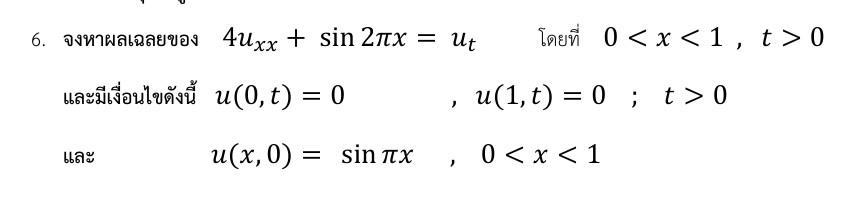

clear;clearvars;clf;
% Parameters
L = 1;            % Length of the spatial domain
Nx = 100;         % Number of spatial grid points
x = linspace(0, L, Nx)'; % Spatial grid
dx = x(2) - x(1); % Spatial step size

T = 1;            % Total simulation time
Nt = 500;         % Number of time steps
tspan = linspace(0, T, Nt); % Time grid

% Differential operator matrix for 4u_xx
e = ones(Nx, 1);
A = spdiags([e -2*e e], -1:1, Nx, Nx) / dx^2; 
A = 4 * A; % Coefficient of u_xx is 4
A(1, :) = 0; A(end, :) = 0; % Boundary conditions

% Initial condition
u0 = sin(pi * x);

% Solve using ODE solver
rhs = @(t, u) A * u + sin(2 * pi * x); % Define the right-hand side of the PDE
[~, U] = ode45(rhs, tspan, u0); % Solve the system of ODEs

% Plot the solution
[X, T] = meshgrid(x, tspan); % Create grids for plotting
U = reshape(U, Nt, Nx);

figure;
surf(X, T, U, 'EdgeColor', 'none');
xlabel('x'); ylabel('t'); zlabel('u(x,t)');
title('Solution of 4u_{xx} + sin(2\pi x) = u_t');